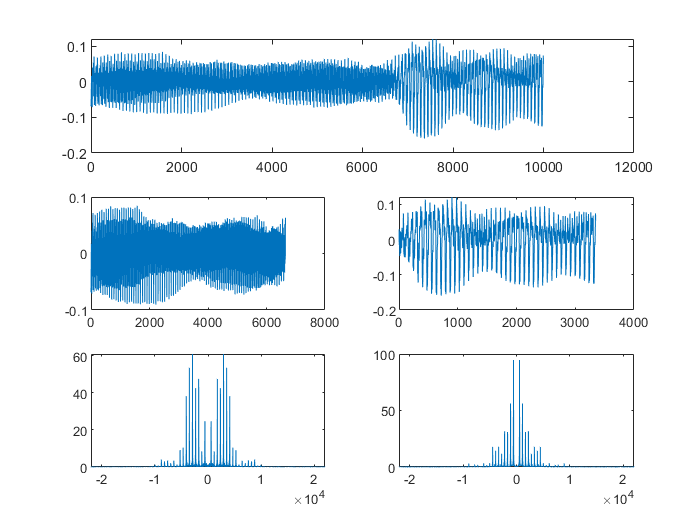

[notes,fsampling] = audioread('exercise notes.wav');
subplot(3,1,1);
plot(notes);
subplot(3,2,3);
plot(notes(1:6650));
subplot(3,2,4);
plot(notes(6651:10000));
N = 16384;
F1=fftshift(abs(fft(notes(1:6650),N))); 
F2=fftshift(abs(fft(notes(6651:10000),N))); 
newX=-fsampling/2 : fsampling/N : fsampling/2 - fsampling/N;
subplot(3,2,5);
plot(newX, F1);
subplot(3,2,6);
plot(newX, F2);